clear; clc; close all;

folder = './data';

data = [load(fullfile(folder, 'experiment_01.txt'));
    load(fullfile(folder, 'experiment_02.txt'));
    load(fullfile(folder, 'experiment_03.txt'));
    load(fullfile(folder, 'experiment_04.txt'));
    load(fullfile(folder, 'experiment_05.txt'))];

x = data(:,1);
y = data(:,2);
z = data(:,3);

sum(x <= 0) 

ans = 0

sum(y <= 0)

ans = 0

sum(z <= 0)

ans = 2836

% Flags um bestimmte Sektion auszuführen

%bestes modell D=8000
run_fit = true;

%kleines modell D=300
run_reduced_dim_fit = true;

%hyperparameter tuning mit gridsearch
run_tuning = false;

%vorherige Ideen als presets/koniguration
run_hist = false;

%versuche ein besseres modell zu finden
run_experimental_fit = false

run_experimental_fit = logical
   0


function plot_diagnostics(z_obs, z_pred)

blue_color = [0 0.4470 0.7410];   % MATLAB Standard-Blau

figure('Position', [100, 100, 1200, 500]);

% --- Subplot 1: Korrelationsplot ---
subplot(1,2,1);

ss_res = sum((z_obs - z_pred).^2);
ss_tot = sum((z_obs - mean(z_obs)).^2);
r2 = 1 - ss_res / ss_tot;

scatter(z_obs, z_pred, 5, blue_color, 'filled', 'MarkerFaceAlpha', 0.2);
hold on;

ax_min = min([z_obs; z_pred]);
ax_max = max([z_obs; z_pred]);
plot([ax_min, ax_max], [ax_min, ax_max], 'k-', 'LineWidth', 1.5);

xlabel('Beobachtete Werte $z$', 'Interpreter', 'latex');
ylabel('Vorhergesagte Werte $\hat{z}$', 'Interpreter', 'latex');
title('Korrelationsplot $z$ und $\hat{z}$', 'Interpreter', 'latex');

text(0.05, 0.92, sprintf('$R^2 = %.4f$', r2), ...
    'Units', 'normalized', ...
    'FontSize', 16, ...
    'Interpreter', 'latex');

axis equal;
xlim([ax_min, ax_max]);
ylim([ax_min, ax_max]);
grid on;
hold off;

% --- Subplot 2: Residuen-Histogramm ---
subplot(1,2,2);

residuals  = z_obs - z_pred;
sigma_theo = 0.5;
mu_theo    = 0;

histogram(residuals, 30, ...
    'FaceColor', blue_color, ...
    'Normalization', 'pdf', ...
    'FaceAlpha', 0.3, ...
    'DisplayName', 'Dichte');
hold on;

[f_emp, xi] = ksdensity(residuals);
plot(xi, f_emp, ...
    'Color', blue_color, ...
    'LineWidth', 2, ...
    'DisplayName', 'Empirische Dichtefunktion');

r_range = linspace(min(residuals), max(residuals), 200);
result_pdf = (1/(sigma_theo*sqrt(2*pi))) * ...
    exp(-((r_range - mu_theo).^2) / (2*sigma_theo^2));

plot(r_range, result_pdf, ...
    'k--', ...
    'LineWidth', 2, ...
    'DisplayName', 'Theoretische Dichtefunktion $\mathcal{N}(0,0.5^2)$');

xline(0, 'k:', 'LineWidth', 1, 'HandleVisibility', 'off');

xlabel('Residuen $z - \hat{z}$', 'Interpreter', 'latex');
ylabel('Dichte', 'Interpreter', 'latex');
title('Empirische und theoretische Dichtefunktion der Residuen', ...
    'Interpreter', 'latex');

legend('Location', 'northeast', 'Interpreter', 'latex');
grid on;
hold off;

end

function [best_model, best_opts, results_matrix] = tune_rff_svd(X0, z, base_opts, D_list, kw_list, lambda_list)
% helper for gridsearch tuning
    
        best_R2 = -inf;
        results_matrix = [];
        total = numel(D_list) * numel(kw_list) * numel(lambda_list);
        count = 0;
        fprintf('Starting Grid Search for %d combinations\n', total);

        for D = D_list
            for kw = kw_list
                for lambda = lambda_list
                    count = count + 1;
                    
                    fprintf('Progress: %d/%d (%.1f%%) \r', ...
                        count, total, 100*count/total);

                    current_opts = base_opts;
                    current_opts.D = D;
                    current_opts.kw_rff = kw;
                    current_opts.lambda = lambda;



                    model = train_rff_svd(X0, z, current_opts);
                    z_pred = predict_rff_svd(model, X0);

                    residuals = z - z_pred;
                    sigma = std(residuals);

                    ss_res = sum((z - z_pred).^2);
                    ss_tot = sum((z - mean(z)).^2);
                    R2 = 1 - ss_res / ss_tot;

                    RMSE = sqrt(mean((z - z_pred).^2));
                    
                    results_matrix = [results_matrix; D, kw, lambda, R2, RMSE];

                    if R2 > best_R2
                        best_R2 = R2;
                        best_model = model;
                        best_opts = current_opts;
                        fprintf('New best R2 -> D=%-5d, kw=%-5.3f, lambda=%-8.6e, R2 = %.4f, sigma = %.4f\n', ...
                            D, kw, lambda, R2, sigma);
                    end
                end
            end
        end
        fprintf('\nGrid Search Complete\n');
end

function X0 = build_features(x, y)
% function for feature engineering and design matrix construction

r = sqrt(x.^2 + y.^2); 
% r: Euklidische Distanz (Radius) zum Ursprung.
% Mit der Annahme, dass Signale aus einem Zentrum stammen.


X0 = [
    x, y, r, ...
    x.*y, x.*r, y.*r, ...
    x.^2, y.^2, ...
    log(x), log(y), log(r), ...
    ];

% Hinweis: Eine Logarithmierung ist zulässig, da x und y ausschließlich positive Werte aufweisen.

end

function evaluate_model(z, z_pred, plot)
% function for model diagnostics

if nargin < 3
    plot = false;
end

residuals = z - z_pred;

RMSE = sqrt(mean(residuals.^2));
sigma = std(residuals);

R2 = 1 - sum(residuals.^2) / sum((z - mean(z)).^2);

fprintf('Mean residuals: %.6f\n', mean(residuals));
fprintf('RMSE: %.6f\n', RMSE);
fprintf('Sigma: %.6f\n', sigma);
fprintf('R2: %.6f\n', R2);

if plot
figure;
scatter(z_pred, residuals, 1, 'filled');
xlabel('Predicted z');
ylabel('Residuals');
title('Residuals vs Predicted');
grid on;

figure;
scatter(z_pred, z, 1, 'filled');
xlabel('Predicted z');
ylabel('Real z');
title('Real vs Predicted');
grid on;


figure;
qqplot(residuals);
title('Q-Q Plot');
end

end


function z_pred = predict_rff_svd(model, X0)
% function for generating model predictions (z_pred)

    n = size(X0,1);
    
    % Standardize using model config
    X_proc = (X0 - model.mu) ./ model.sig;

    % Rff & Concatenation
    if model.use_rff
        fourier = sqrt(2/model.D) * cos(X_proc * model.W + model.b);
        if model.keep_basis
            fourier = [X_proc, fourier];
        end
    else
        fourier = X_proc;
    end

    % Add Bias and Predict
    fourier = [ones(n,1), fourier];
    z_pred = fourier * model.alpha;
end

function opts = rff_svd_options(varargin)
    % Configuration module for model training parameters

    % Core Parameters
    opts.lambda      = 0.0001; % Ridge regularization
    opts.D           = 8000;   % Number of RFF features
    opts.kw_rff      = 1.0;    % Kernel Bandwidth parameter
    opts.seed        = 0;      % Random seed
    opts.tuning_mode = "grid"; % default tuning mode
    
  
    opts.use_rff     = true;   % Use RFF 
    
    opts.keep_basis  = false;  % Keep original X0 alongside RFF?
    
    opts.standardize = false;  % Turn Z-score standardization?

    opts.use_tsvd    = false;  % Use Truncated SVD? 
    opts.tsvd_gamma  = 0.99;   % trunctuated threshold if TSVD is ON

    % Overwrite defaults with any external provided flags/toggles
    for i = 1:2:length(varargin)
        opts.(varargin{i}) = varargin{i+1};
    end
end


function model = train_rff_svd(X0, z, opts)
% training pipeline

    if nargin < 3 || isempty(opts)
        opts = rff_svd_options(); 
    end

    n = size(X0,1);
    d = size(X0,2);
    rng(opts.seed); 

    % standarization
    if opts.standardize
        mu = mean(X0, 1);
        sig = std(X0, 0, 1); 
        sig(sig == 0) = 1; 
        X_proc = (X0 - mu) ./ sig;
    else
        mu = zeros(1, d); 
        sig = ones(1, d);
        X_proc = X0;
    end

    % Einschub:
    % Im Bericht steht für Rff die mathematische Formel, welche pro Inputvektor (per sample) berechnet wird.
    % Im code wird es insgesamt (vektorisiert) berechnet (Statt Vektor haben wir die Featurematrix als Input). 
    % Es ändert sich nur die Reihenfolge von W * x zu X0 * W

    % Random Fourier Features (RFF) sind eine Approximation eines nicht-linearen Gauß-Kernels (RBF).
    % kw_rff skaliert W als Auflösung: Kleine Werte zeigen jedes Detail, große Werte machen die glätten Approximation.

    % Rff & feature concatenation
    if opts.use_rff
        W = randn(d, opts.D) / opts.kw_rff;
        b = 2*pi*rand(1, opts.D);
        fourier = sqrt(2/opts.D) * cos(X_proc * W + b);
        
        if opts.keep_basis
            fourier = [X_proc, fourier]; % Combine basis features + RFF features
        end
    else
        W = []; b = []; 
        opts.D = d;
        fourier = X_proc;
    end

    % Add bias column
    fourier = [ones(n,1), fourier];

    % SVD & TSVD
    [U, S, V] = svd(fourier, 'econ');
    s = diag(S);
    
    if opts.use_tsvd
        energy = cumsum(s.^2) / sum(s.^2);
        w = find(energy >= opts.tsvd_gamma, 1);
        if isempty(w), w = length(s); end
        U = U(:, 1:w);
        V = V(:, 1:w);
        s = s(1:w);
    end

    % Einschub:
    % Normale OLS Lösung (Normalengleichung): alpha = (X'*X)^-1 * X'*z
    % Ridge Regression / OLS mit strafterm l2 Variante: alpha = (X'*X + lambda*I)^-1 * X'*z
    % 
    % Anstatt die Matrix X'*X direkt zu invertieren (was numerisch instabil ist), 
    % nutzen wir die SVD: X = U*S*V'. Eingesetzt in die Normalengleichung:
    % alpha = V * (S^2 + lambda*I)^-1 * S * U' * z


    % Solve with ridge
    alpha = V * diag(s ./ (s.^2 + opts.lambda)) * U' * z;

    % store model
    model = opts; % pass current configuration of model
    model.alpha = alpha; % fitted/trained parameters
    model.W = W; % RFF: random projection matrix
    model.b = b; % RFF: random offset
    model.mu = mu; % Mean of X0 (for Z-Score Standardization)
    model.sig = sig; % Std of X0 (for Z-Score Standardization)
    model.s = s; % Singular values of SVD
end

X0 = build_features(x, y);

disp(size(X0, 2))

    11



%old configurations

manual_features = rff_svd_options( ...
    'use_rff', false, ...
    'lambda', 0, ...
    'standardize', false, ...
    'use_tsvd', false);

svd_ridge = rff_svd_options( ...
    'use_rff', false, ...
    'lambda', 0.0001, ...
    'standardize', true, ...
    'use_tsvd', false);

tsvd = rff_svd_options( ...
    'use_rff', false, ...
    'lambda', 0.0001, ...
    'standardize', true, ...
    'use_tsvd', true, ...
    'tsvd_gamma', 0.99);

rff_basis = rff_svd_options( ...
    'use_rff', true, ...
    'keep_basis', true, ...
    'lambda', 0.0001, ...
    'D', 500, ...
    'kw_rff', 1);

no_standardization = rff_svd_options( ...
    'use_rff', true, ...
    'keep_basis', true, ...
    'standardize', false, ...
    'lambda', 0.0001, ...
    'D', 500, ...
    'kw_rff', 1);

no_tsvd = rff_svd_options( ...
    'use_rff', true, ...
    'keep_basis', true, ...
    'standardize', false, ...
    'use_tsvd', false, ...
    'lambda', 0.0001, ...
    'D', 500, ...
    'kw_rff', 1);

no_basis = rff_svd_options( ...
    'use_rff', true, ...
    'keep_basis', false, ...
    'standardize', false, ...
    'use_tsvd', false, ...
    'lambda', 0.0001, ...
    'D', 500, ...
    'kw_rff', 1);

Basic: manual feature engineering 

if run_hist
    model_full = train_rff_svd(X0, z, manual_features);

    rank(X0);
    cond(X0)

    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full);
end

stabilize matrix with svd + standartization + ridge

if run_hist
    model_full = train_rff_svd(X0, z, svd_ridge);
    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full);
end

svd to tsvd (um unnötige richtungen zu entfernen die einen kleinen wert haben, bisherige annahme das kleine Werte Noise sind)

if run_hist
    model_full = train_rff_svd(X0, z, tsvd);
    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full);
end

add rff (basis features + rff features)

if run_hist
    model_full = train_rff_svd(X0, z, rff_basis);
    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full);
end

Log(z)-Transformation: Aufgrund nicht-positiver Zielwerte (z <= 0) verworfen

% if run_hist
%     model_full = train_rff_svd(X0, log(z), rff_basis);
%     z_pred_full = predict_rff_svd(model_full, X0);
%     evaluate_model(log(z), z_pred_full);
% end

remove standardization (war eine zeit lang nach der transformation angewandt was keine gewollte wirkung hatte nach der korruktur wurde R2 schlechter, deshalb habe ich es dann später rausgenommen)

if run_hist
    model_full = train_rff_svd(X0, z, no_standardization);
    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full);
end

remove tsvd (R2 wurde besser, bedeutet kleine werte haben doch eine gewisse erklärbarkeit/einfluss und sind dann kein noise)

if run_hist
    model_full = train_rff_svd(X0, z, no_tsvd);
    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full);
end

basis features haben keinen wirklichen einfluss mehr deshab werden sie nicht mehr konkateniert

if run_hist
    model_full = train_rff_svd(X0, z, no_basis);
    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full);
end

best model

opts = rff_svd_options('lambda', 0.000100, 'D', 8000, 'kw_rff', 1);

Mean residuals: 0.000000
RMSE: 0.527194
Sigma: 0.527200
R2: 0.924096


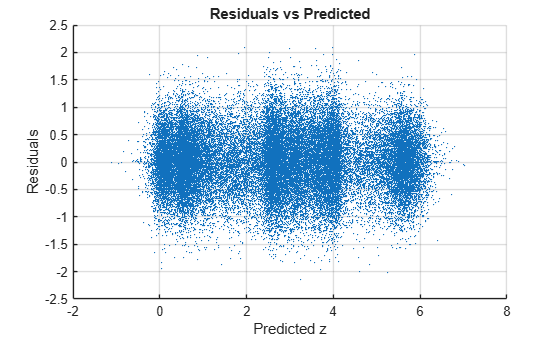

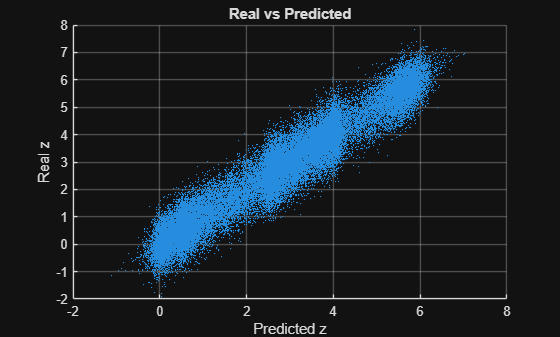

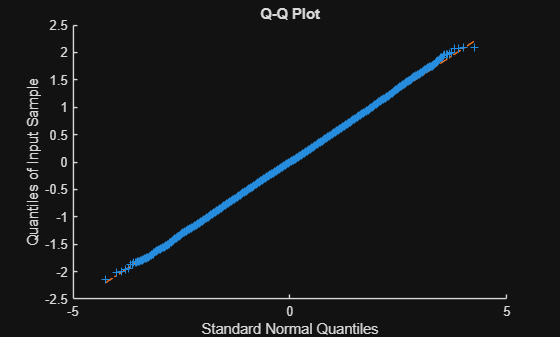

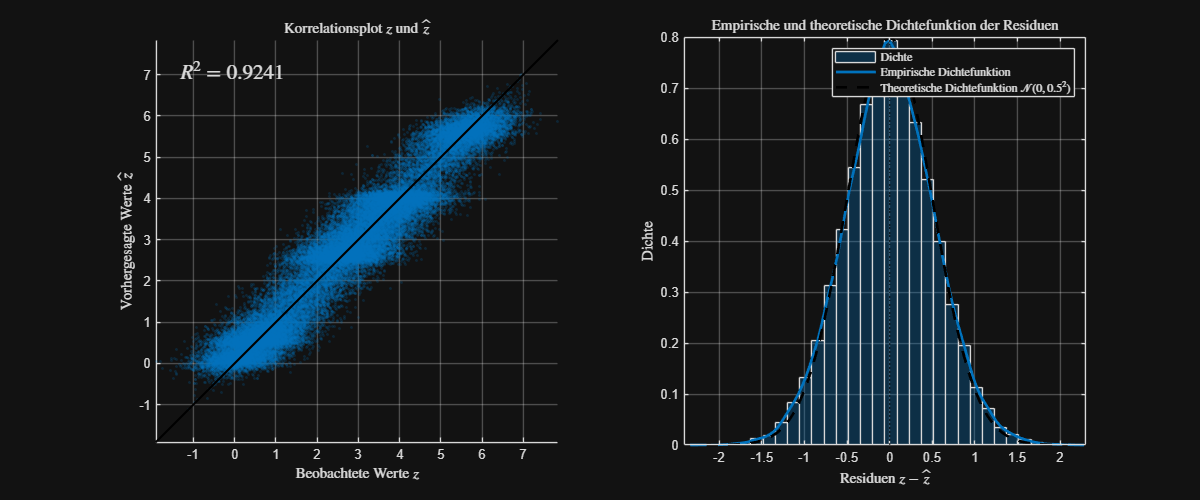

if run_fit
    model_full = train_rff_svd(X0, z, opts);
    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full, true);

    plot_diagnostics(z, z_pred_full);
end

experimental

experimental_opts = rff_svd_options('lambda', 0, 'D', 300, 'kw_rff', 4.6475);

if run_experimental_fit
    model_full = train_rff_svd(X0, z, experimental_opts);
    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full);
end

nach tuning kleineres modell gefunden

reduced_dim_opts = rff_svd_options('lambda', 0, 'D', 300, 'kw_rff', 4.6475);

Mean residuals: 0.000000
RMSE: 0.625384
Sigma: 0.625391
R2: 0.893188


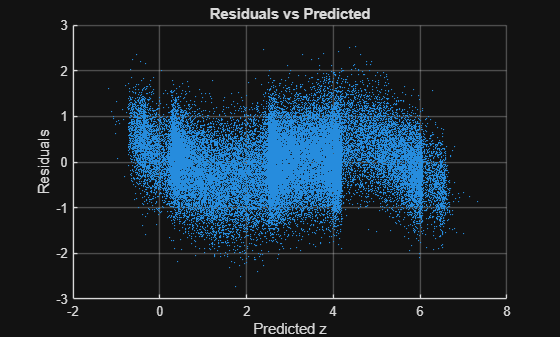

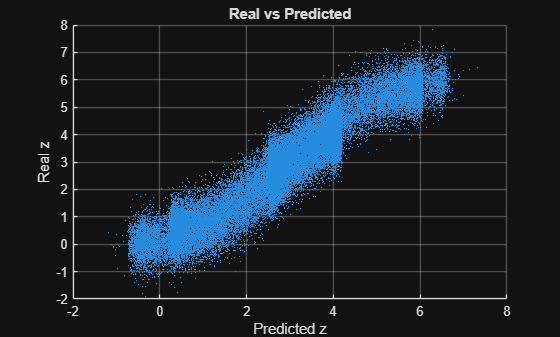

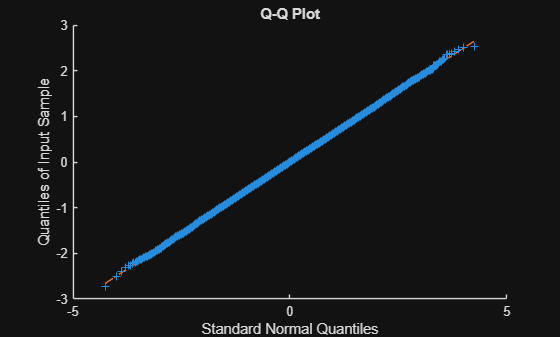

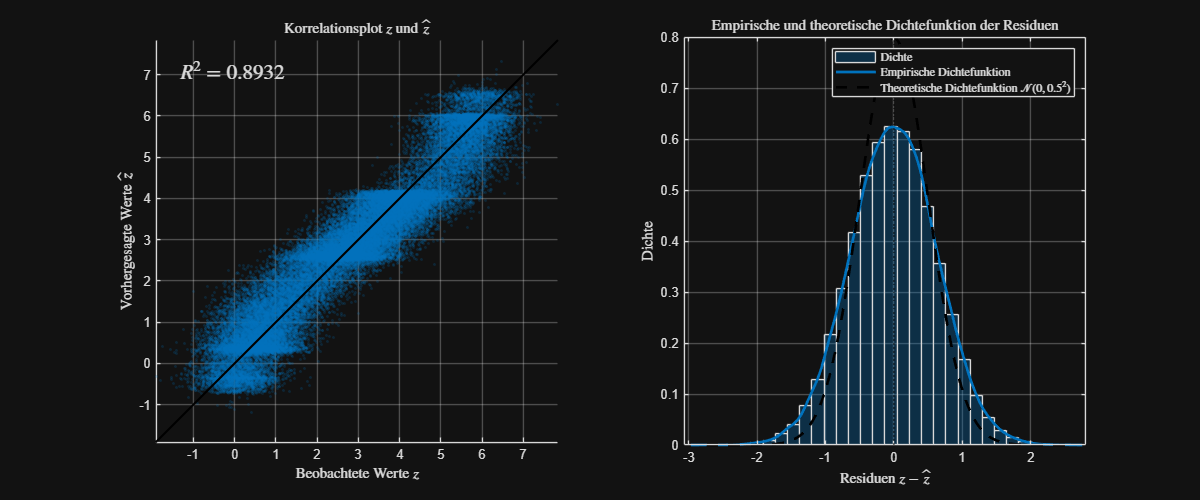

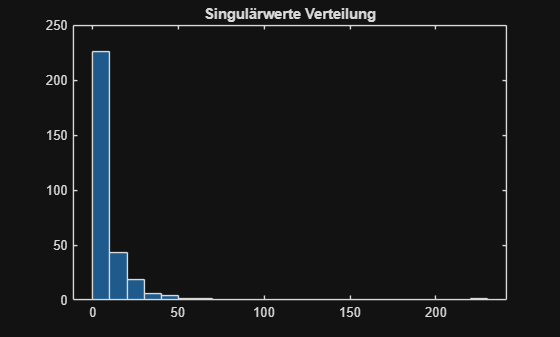

if run_reduced_dim_fit
    model_full = train_rff_svd(X0, z, reduced_dim_opts);
    z_pred_full = predict_rff_svd(model_full, X0);
    evaluate_model(z, z_pred_full, true);

    plot_diagnostics(z, z_pred_full);

    figure;
    histogram(model_full.s);
    title('Singulärwerte Verteilung');

end

Tuning

tuning_opts = experimental_opts

tuning_opts = struct with fields:
         lambda: 0
              D: 300
         kw_rff: 4.6475
           seed: 0
    tuning_mode: "grid"
        use_rff: 1
     keep_basis: 0
    standardize: 0
       use_tsvd: 0
     tsvd_gamma: 0.9900


if run_tuning
    disp('Running Hyperparameter Tuning')

    % Define the grids
    kw_list     = [linspace(1, 4, 100)];
    lambda_list = [0];
    D_list      = [300];

    
    [best_model, best_opts, results_matrix] = tune_rff_svd(X0, z, tuning_opts, D_list, kw_list, lambda_list);

end

if run_tuning

    % Print the optimal hyperparameters found during grid search
    fprintf('Best D: %d\n', best_opts.D);
    fprintf('Best kw: %.4f\n', best_opts.kw_rff);
    fprintf('Best lambda: %.6f\n', best_opts.lambda);

    % Recalculate best R2 from results matrix
    best_R2_found = max(results_matrix(:, 4));
    fprintf('Best R2: %.4f\n', best_R2_found);

    % Filter models based on a custom R2 threshold
    filter = results_matrix(:,4) >= 0.8;
    filtered_results = results_matrix(filter, :);


    % Visualization: 3D Scatter plot of the hyperparameter space
    % X-Axis: D, Y-Axis: kw, Z-Axis: lambda. The color represents the R2 score.
    figure;
    scatter3(filtered_results(:,1), filtered_results(:,2), filtered_results(:,3), filtered_results(:,4), 'filled');
    xlabel('D'); ylabel('kw'); zlabel('lambda');
    title('R2 Hyperparameter');
    colorbar; colormap turbo; grid on;
    view(3);
    hold off;

    z_pred_best = predict_rff_svd(best_model, X0);
    evaluate_model(z, z_pred_best)

end

Weitere erkenntisse: lambda nähert sich der null an beim tuning (weil wir full fit machen brauchen wir nicht mal ridge regularisierung (l2 norm) mehr)

dadurch kann man D fixieren und hat dann nur einen hyperparameter die kernel breite bzw. die auflösung übrig.

Alle Erkenntnisse zusammengefasst:

- log transform von z, standardisierung der feature matrix (auch nur x, y ausprobiert) und Tsvd verschlechtern R2 

- Radiale features (Signale kommt aus einem Zentrum als Annahme) funktionieren gut

- Daten haben im Querschnitt einen SInusoid Profil

- Neue Basis features hinzufügen ist sehr fragil. R2 wird ziemlich schnell im negativen landen

- doppelte Regularisierung hat geschadet (Tsvd + Ridge) --> Tsvd wurde zuerst entfernt (Mit Tsvd gab es mehr ausreißer laut QQ-Plot)

- Train/test split bzw. Crossvalidation nicht nötig da wir Fullfit durchführen --> Overfitting und Genralisierung ist nicht das Ziel --> Ridge regularisierung nicht mehr nötig (Erkenntiss beim Tuning)

-  Basis features sind im Vergleich zu den Rff features nicht mehr EInflussreich --> Basis features werden nicht mehr konkateniert

- Ab einen gewissen D und kernel breite ändert sich R2 nicht mehr so stark

Ausblick/Ideen:

- Outlier handling mit geschlossener Form finden

- W und b mit einer anderen Verteilung zufällig initialisieren

- Bias rausnehmen

- Statt Gridsearch was anderes verwenden (Random search)

- Die transformierten Daten irgendwie visualisieren

- Besseren Zufall/Sampling verwenden

- Herausfinden welche Rff features den größten Einfluss haben 

- Orthogonales Rff verwenden

- Splines Ansatz

- Triangulierung Ansatz

Kurse für Refernzen/Quellen:

Diagnostik - Stat2

Splines Idee, Orthogonale Basen Idee - Approximations Theorie

Stochastisch/ Monte Carlo Ansatz - Uncertainty Quantification/ ModSim

Fourier - Computer Grafik